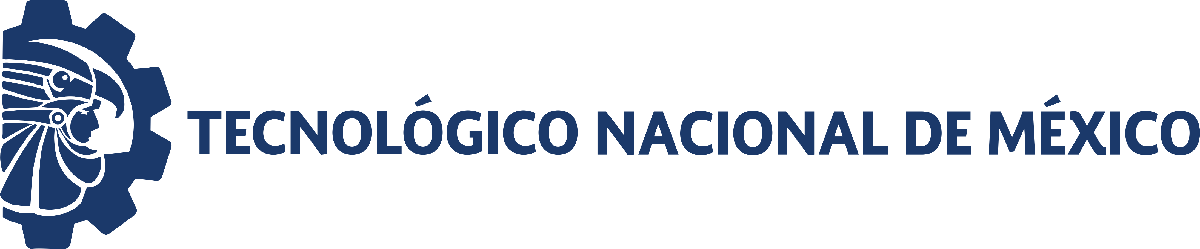                                 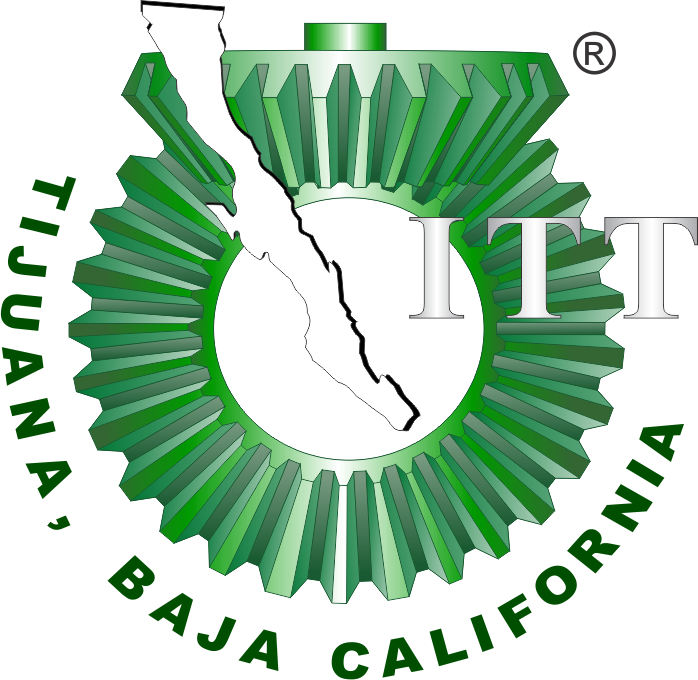

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

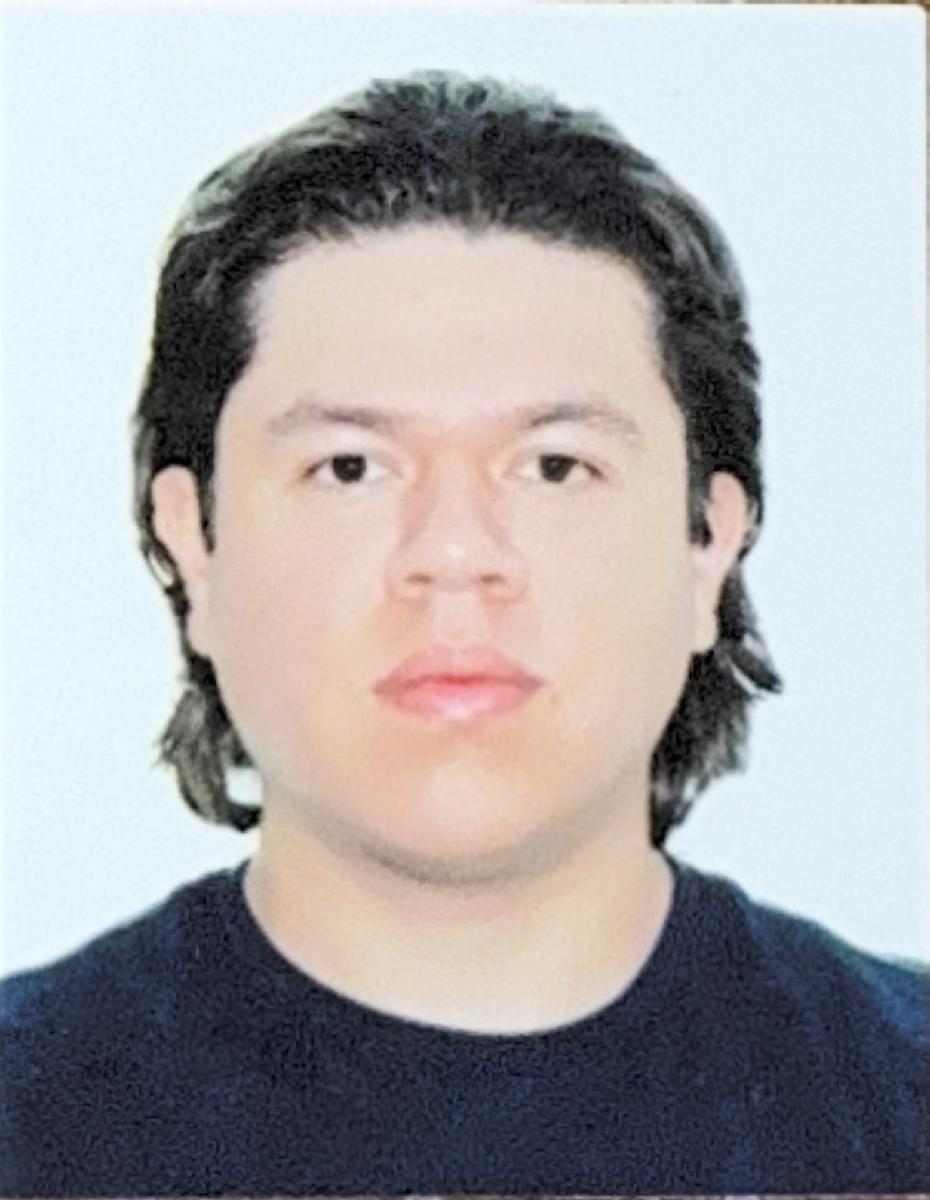

Nombre del alumno: Carlos Azael Ramirez Rodriguez

Número de control: 22212267

Correo institucional: L22212267**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaA'

file = 'SistemaA'

open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta al escalón

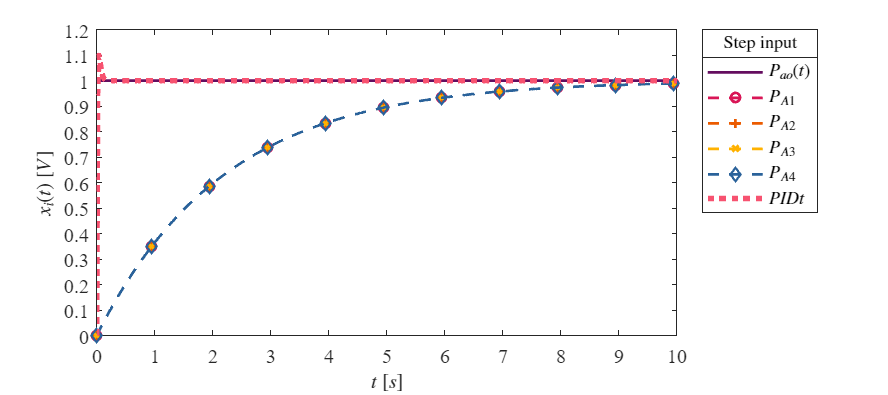

Signal = 'Step';
set_param('SistemaA/S1','sw','1');
set_param('SistemaA/Pao(t)','sw','1');
x1 = sim(file,parameters);

plotsignals(x1.t,x1.Pao,x1.PA1,x1.PA2,x1.PA3,x1.PA4,x1.PID,Signal)

## Respuesta al impulso

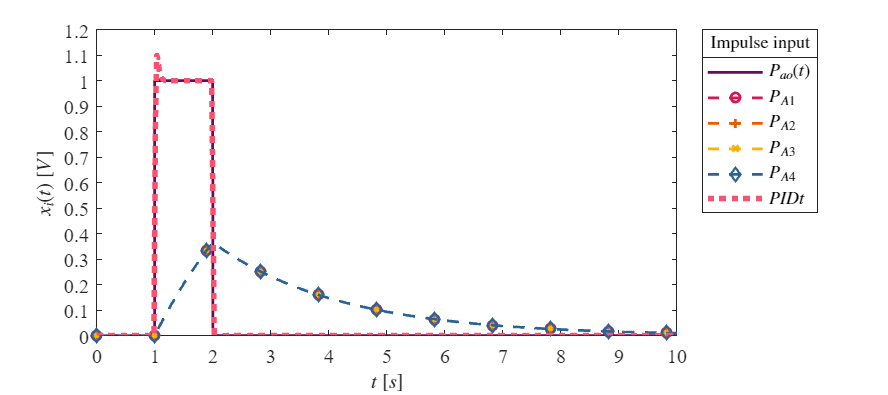

Signal = 'Impulse';
set_param('SistemaA/S1','sw','0');
set_param('SistemaA/Pao(t)','sw','1');
x2 = sim(file,parameters);

plotsignals(x2.t,x2.Pao,x2.PA1,x2.PA2,x2.PA3,x2.PA4,x2.PID,Signal)

## Respuesta a la rampa

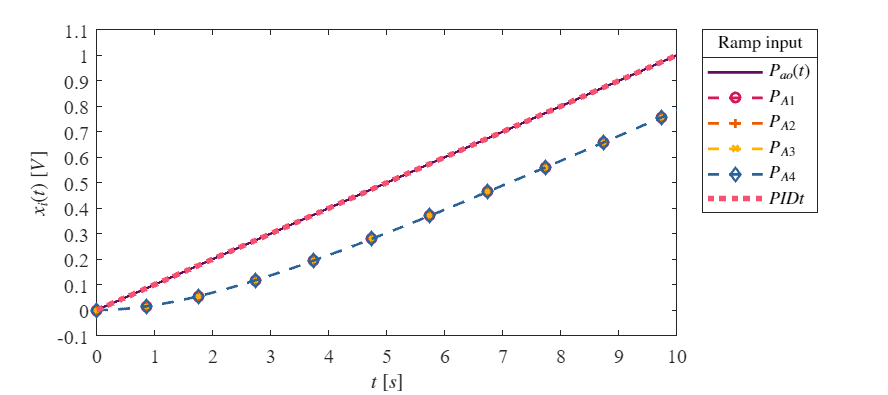

Signal = 'Ramp';
set_param('SistemaA/S2','sw','1');
set_param('SistemaA/Pao(t)','sw','0');
x3 = sim(file,parameters);

plotsignals(x3.t,x3.Pao,x3.PA1,x3.PA2,x3.PA3,x3.PA4,x3.PID,Signal)

## Respuesta a la función sinusoidal

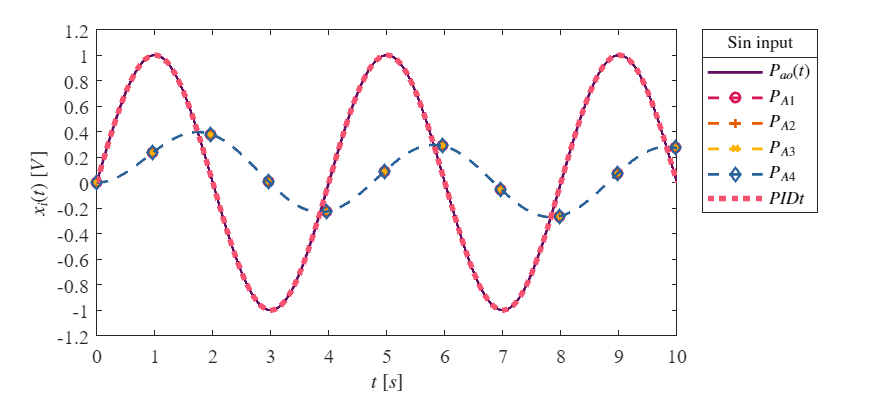

Signal = 'Sin';
set_param('SistemaA/S2','sw','0');
set_param('SistemaA/Pao(t)','sw','0');
x4 = sim(file,parameters);

plotsignals(x4.t,x4.Pao,x4.PA1,x4.PA2,x4.PA3,x4.PA4,x4.PID,Signal)

## Función: Respuesta a las señales

function plotsignals(t,Pao,PA1,PA2,PA3,PA4,PID,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [100,13,95;
                217,22,86;
                235,91,0;
                255,178,0;
                42,98,154;
                247,82,112]/255;
    colororder(mycolors)
    p = plot(t,Pao,'-',t,PA1,'--o',t,PA2,'--+',t,PA3,'--x',t,PA4,'--d',t,PID,':',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(6),'LineWidth',3);
    L = legend('$P_{ao}(t)$','$P_{A1}$','$P_{A2}$','$P_{A3}$','$P_{A4}$','$PID{t}$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],'FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10);

    if Signal == "Step" || Signal == "Impulse"
        ylim([0,1.2]); yticks(0:0.1:1.2)
    elseif Signal == "Ramp"
        ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    elseif Signal == "Sin"
        ylim([-1.2 1.2]); yticks(-1.2:0.2:2)
    end
    
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')
end


